# Tuning ottimale controllore PID - joint 1

## Schema di controllo

**Decentralizzato**

Un controllore indipendente per ogni giunto. Le mutue influenze tra giunti sono viste come disturbi causati da un sistema sull'altro.

Eseguiamo il tuning di ciascun controllore nel dominio continuo sfruttando il modello continuo del processo e in seguito discretizziamo il controllore ottenuto.

## Struttura di controllo (per il singolo giunto)

**Controllo in cascata: posizione → velocità**

Ogni giunto è controllato da un controllore che riceve in input PV.POS e PV.VEL misurate e il set-point SP. All'interno del controllore, alloggia il doppio loop, costituito da:

- un *P + LPF* per il **loop interno **(input: PV.VEL + MV del Cp + FFW.VEL - output: coppia fornita all'attuatore)

- un *PI* per il **loop esterno** (input: PV.POS e SP.POS - output: velocità fornita in input al controllore interno)

- FFW.TORQUE in input all'attuatore.

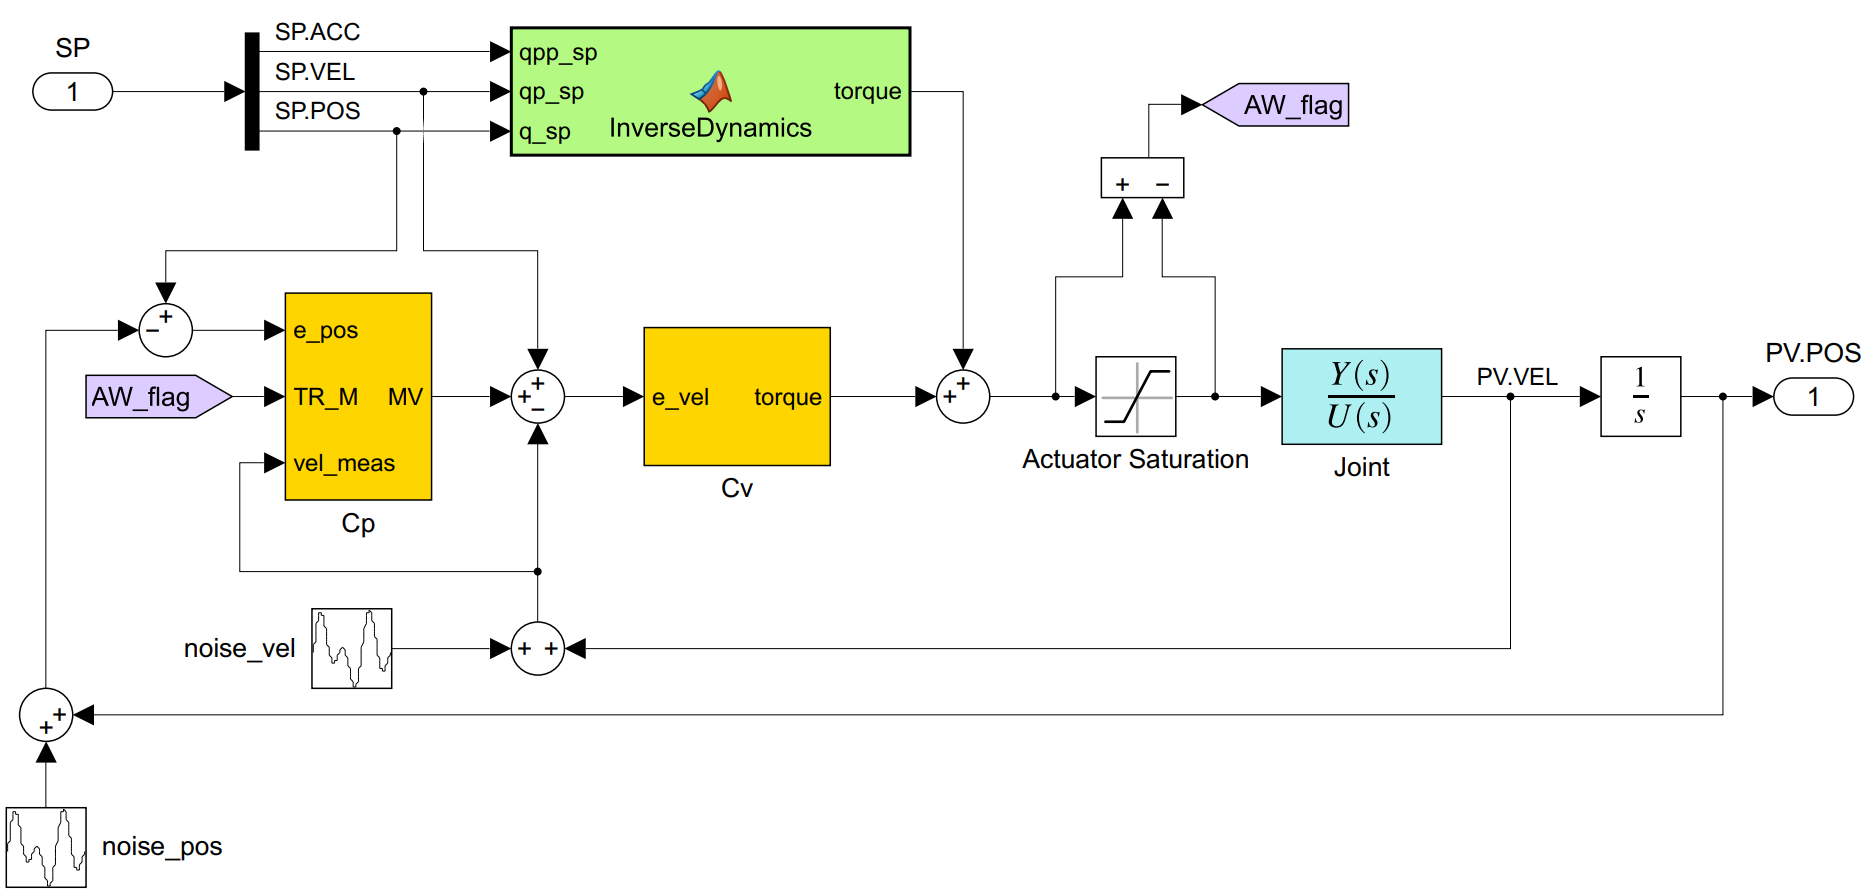

## Taratura ottima con vincoli robusti

Determinare i parametri del controllore $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizzi una cifra di merito.

L'equazione del controllore è quella di un PID in **forma parallela **(separazione delle tre azioni) con l'aggiunta di un filtro complessivo. A seconda delle esigenze,si possono settare a zero i parametri corrispondenti alle azioni che vogliamo escludere. In particolare, l'uso del filtro sull'azione derivativa e di quello complessivo sull'azione di controllo deve essere mutualmente esclusivo.

   
$$C(s)=PID_{filt}(s)=\left(K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_{fd}s+1}\right) \cdot \frac{1}{T_{fu}s+1}$$


### Caricamento modelli dei processi

clear; clc;

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

simulation.author = 'CL_M';    % selezionare autore della simulazione
Nprova = 21;    % numero della simulazione

modelName = strcat(simulation.author,'_model_', num2str(Nprova)); 
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);   % carico il modello


Scelta dell'intervallo di frequenze d'interesse

w_inf = 0.1;
w_sup = 3000;

### Loop interno: **P con filtro su tutta l'azione di controllo**

Processo da controllare (coppia motore → velocità)

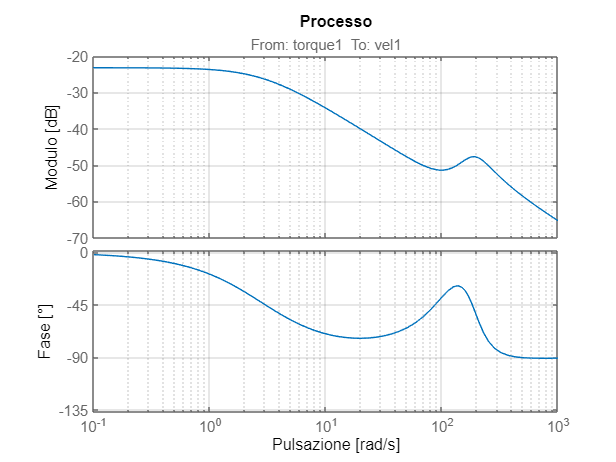

process = modelC_joint1;    % nella forma dello spazio degli stati

figure
bodeplot(process)
grid on; title('Processo');

axes = findall(gcf,'type','axes');
ay=get(axes(3),'YLabel'); set(ay,'String','Modulo [dB]');
ay=get(axes(2),'YLabel'); set(ay,'String','Fase [°]');
ax=get(axes(1),'XLabel'); set(ax,'String','Pulsazione [rad/s]')

% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'.\presentation\control\processo_int_joint1.emf')

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 60;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process,internal_joint1.wc_des);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
internal_joint1.MS = 2;

% Reiezione disturbo di misura
internal_joint1.wh = 2000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 10;
internal_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dl_max, internal_joint1.PM_min);

#### Ottimizzatore interno

Parametri da tarare

inner_optim = false;    % selezionare per effettuare l'ottimizzazione
if inner_optim

    timeout = 60*10;    % tempo massimo di simulazione (in secondi)
    optimizer = "GlobalSearch";    % scelta dell'algoritmo di ottimizzazione

    % [valore iniziale, limite inferiore, limite superiore]
    internal_joint1.aKp = [500, 100, 1000];
    internal_joint1.aKi = [0, 0, 0];
    internal_joint1.aKd = [0, 0, 0];
    internal_joint1.aTfd = [0, 0, 0];
    internal_joint1.aTfu = [1/70, 1/100, 1/40];
    
    % Lanciare ottimizzatore
    x = PID_param_optimization(internal_joint1.aKp,internal_joint1.aKi,internal_joint1.aKd,...
                               internal_joint1.aTfd,internal_joint1.aTfu,J,nlcon,timeout,optimizer)

    Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);
    
    % Print delle frequenze dei filtri
    if Tfd ~=0
        fTfd = 1/Tfd
    end
    if Tfu ~=0
        f_Tfu = 1/Tfu
    end
end

#### Controllore interno

s = tf('s');    % variabile s per il dominio delle frequenze
manual_overwriting_int = false;    % selezionare per effettuare il tuning manuale
use_saved_inner = true;           % selezionare per caricare un controllore salvato

if manual_overwriting_int && ~use_saved_inner
    Kp = 300;
    Ki = 0;
    Kd = 0;
    Tfd = 0;
    Tfu = 1/63;

elseif use_saved_inner && ~manual_overwriting_int
    load('.\src\controllers\params\PID_int_joint1.mat')    % carico il controllore
    Kp = PID_int_joint1.Kp;
    Ki = PID_int_joint1.Ki;
    Kd = PID_int_joint1.Kd;
    Tfd = PID_int_joint1.Tfd;
    Tfu = PID_int_joint1.Tfu;

elseif use_saved_inner && manual_overwriting_int    % controllo sulla selezione delle checkbox
    error('Controllare la selezione delle checkbox: sono state selezionate entrambe.')
end

% progettiamo un controllore nella forma della funzione di trasferimento
Cv_joint1 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);
Cv_joint1.InputName = 'sp-vel';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = process*Cv_joint1;    % funzione di anello aperto interna

Grafici dei risultati

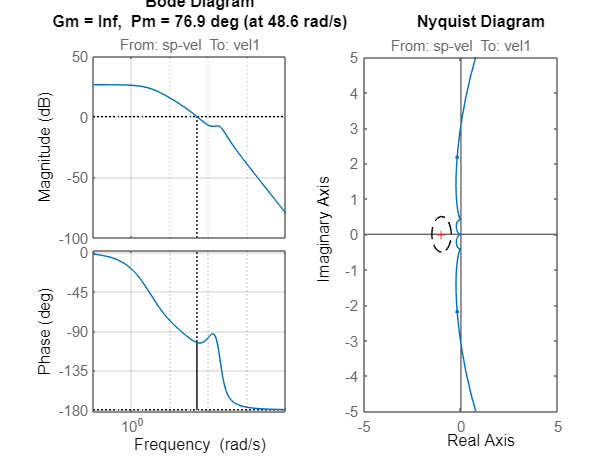

figure;
subplot(1,2,1)
margin(Loop_int_joint1)
grid on; hold on
hold off

subplot(1,2,2)
nyquist(Loop_int_joint1)
axis equal; hold on;
angolo=linspace(-pi,pi);
plot(-1+1/internal_joint1.MS*sin(angolo),1/internal_joint1.MS*cos(angolo),'--k')    % cerchio limite per MS
xlim([-5 5]); ylim([-5 5]);

Titolo ed etichette assi personalizzate

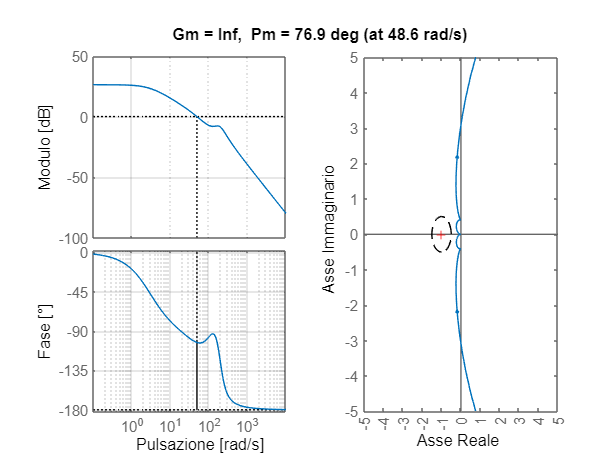

check_figure4print_int = true;    % selezionare per modificare le figure e salvarle
if check_figure4print_int
    axes = findall(gcf,'type','axes');
    at = get(axes(5),'title'); at.String = '';
    at = get(axes(2),'title'); at.String = '';
    at = get(axes(1),'title'); at.String = '';
    at = get(axes(3),'title'); at.FontSize = 11;at.Position = [255 350 0];
    at = get(axes(3),'title'); at.String = at.String{2};
    ay=get(axes(1),'YLabel'); set(ay,'String','Asse Immaginario');
    ax=get(axes(1),'XLabel'); set(ax,'String','Asse Reale');
    ay=get(axes(4),'YLabel'); set(ay,'String','Fase [°]');
    axes(4).XTick = [1,10,100,1000]; axes(2).XTick = -5:1:5;
    ay=get(axes(5),'YLabel'); set(ay,'String','Modulo [dB]');
    ax=get(axes(3),'XLabel'); set(ax,'String','Pulsazione [rad/s]');
    axes(1).YLabel.Position(1) = 1; axes(1).XLabel.Position(1) = 110;
    
    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\control\PID_int_joint1.emf')
end
hold off;

Salvataggio dei parametri tarati nella struttura `PID_int_joint1`

if ~use_saved_inner
    PID_int_joint1.Kp = Kp;
    PID_int_joint1.Ki = Ki;
    PID_int_joint1.Kd = Kd;
    PID_int_joint1.Tfd = Tfd;
    PID_int_joint1.Tfu = Tfu;
    paramsDirectory = '.\src\controllers\params\PID_int_joint1';    
    save(paramsDirectory,'PID_int_joint1')
end

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\textrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


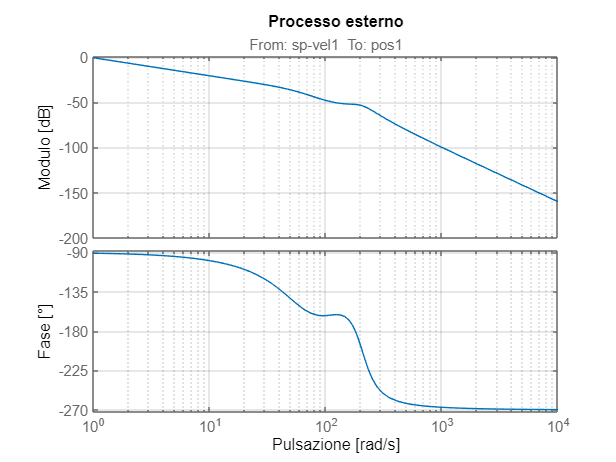

process_ext = minreal(tf(Cv_joint1*modelC_joint1 * 1/(1+Cv_joint1*modelC_joint1)) * 1/s);
process_ext.InputName = 'sp-vel1';
process_ext.OutputName = 'pos1';

figure
bodeplot(process_ext)
grid on; title('Processo esterno');

axes = findall(gcf,'type','axes');
ay=get(axes(3),'YLabel'); set(ay,'String','Modulo [dB]');
ay=get(axes(2),'YLabel'); set(ay,'String','Fase [°]');
ax=get(axes(1),'XLabel'); set(ax,'String','Pulsazione [rad/s]')

% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'.\presentation\control\processo_ext_joint1.emf')

#### Cifra di merito da minimizzare

external_joint1.wc_des = 50;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process_ext,external_joint1.wc_des);

#### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint2.MS = 1.6;

% Reiezione disturbo di misura
external_joint2.wh = 2000;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 1;
external_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 65;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector=logspace(log10(w_inf),log10(w_sup))';
w_vector=sort([w_vector;external_joint2.wl;external_joint2.wh]);

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dl_max, external_joint2.PM_min);

#### Ottimizzatore esterno

Parametri da tarare

ext_optim = false;    % selezionare per effettuare l'ottimizzazione

if ext_optim

    timeout = 60*10;    % tempo massimo di simulazione (in secondi)
    optimizer = "GlobalSearch";    % scelta dell'algoritmo di ottimizzazione

    % [valore iniziale, limite inferiore, limite superiore]
    external_joint1.aKp = [100, 1, 1000];
    external_joint1.aKi = [0.01, 0.001, 1];
    external_joint1.aKd = [0, 0, 0];
    external_joint1.aTfd = [0, 0, 0];
    external_joint1.aTfu = [0, 0, 0];
    
    % Lanciare ottimizzatore
    x = PID_param_optimization(external_joint1.aKp,external_joint1.aKi,external_joint1.aKd, ...
                               external_joint1.aTfd,external_joint1.aTfu,J,nlcon,timeout,optimizer)

    Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);
    
    % Print delle frequenze dei filtri
    if Tfd ~=0
        fTfd = 1/Tfd
    end
    if Tfu ~=0
        f_Tfu = 1/Tfu
    end
end

#### Controllore esterno

manual_overwriting_ext = true;    % selezionare per effettuare il tuning manuale
use_saved_ext = false;    % selezionare per caricare un modello salvato

if manual_overwriting_ext
    Kp = 30;
    Ki = 0.01;
    Kd = 0;
    Tfd = 0;
    Tfu = 0;

elseif use_saved_ext
    load('.\src\controllers\params\PID_ext_joint1.mat')    % carico il controllore
    Kp = PID_ext_joint1.Kp;
    Ki = PID_ext_joint1.Ki;
    Kd = PID_ext_joint1.Kd;
    Tfd = PID_ext_joint1.Tfd;
    Tfu = PID_ext_joint1.Tfu;

elseif use_saved_inner && manual_overwriting_int    % controllo sulla selezione delle checkbox
    error('Controllare la selezione delle checkbox: sono state selezionate.')    % controllo sulla selezione delle checkbox
end

% progettiamo un controllore nella forma della funzione di trasferimento
Cp_joint1 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);
Cp_joint1.InputName = 'sp-pos';
Cp_joint1.OutputName = 'sp-vel';

Loop_ext_joint1 = process_ext*Cp_joint1;    % funzione di anello aperto interna

Grafici dei risultati

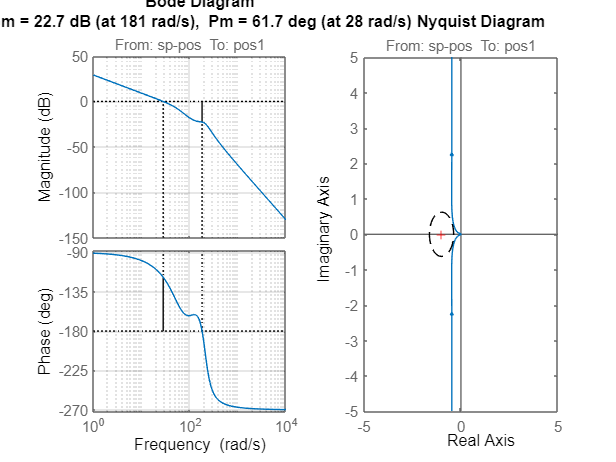

figure
subplot(1,2,1)
margin(Loop_ext_joint1)
grid on; hold on
hold off

subplot(1,2,2)
nyquist(Loop_ext_joint1)
axis equal; hold on;
angolo=linspace(-pi,pi);
plot(-1+1/external_joint2.MS*sin(angolo),1/external_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

Titolo ed etichette assi personalizzate

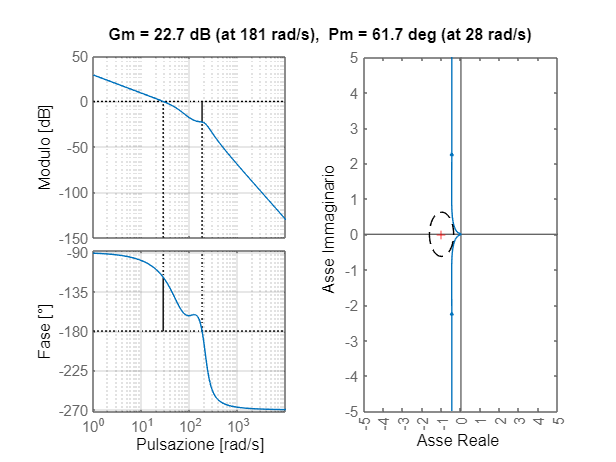

check_figure4print_ext = true;    % selezionare per modificare le figure e salvarle
if check_figure4print_ext
    axes = findall(gcf,'type','axes'); % (1): plot globale, (2): plot fase, (3): plot modulo
    at = get(axes(5),'title'); at.String = '';
    at = get(axes(2),'title'); at.String = '';
    at = get(axes(1),'title'); at.String = '';
    at = get(axes(3),'title'); at.FontSize = 11;at.Position = [255 350 0];
    at = get(axes(3),'title'); at.String = at.String{2};
    ay=get(axes(1),'YLabel'); set(ay,'String','Asse Immaginario');
    ax=get(axes(1),'XLabel'); set(ax,'String','Asse Reale');
    ay=get(axes(4),'YLabel'); set(ay,'String','Fase [°]');
    axes(4).XTick = [1,10,100,1000]; axes(2).XTick = -5:1:5;
    ay=get(axes(5),'YLabel'); set(ay,'String','Modulo [dB]');
    ax=get(axes(3),'XLabel'); set(ax,'String','Pulsazione [rad/s]')
    axes(1).YLabel.Position(1) = 1; axes(1).XLabel.Position(1) = 110;
    
    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\control\PID_ext_joint1.emf')
end

Salvataggio dei parametri tarati nella struttura `PID_ext_joint1`

if ~use_saved_ext
    PID_ext_joint1.Kp = Kp;
    PID_ext_joint1.Ki = Ki;
    PID_ext_joint1.Kd = Kd;
    PID_ext_joint1.Tfd = Tfd;
    PID_ext_joint1.Tfu = Tfu;
    paramsDirectory = '.\src\controllers\params\PID_ext_joint1';    
    save(paramsDirectory,'PID_ext_joint1')
end

## Discretizzazione

st = 1e-3;    % tempo di campionamento

### Loop interno

PID_int_joint1.st = st;

% Discretizzazione della fdt
[PID_int_joint1.coeff_num_D, PID_int_joint1.coeff_den_D] = discretizzazionePID_fn(PID_int_joint1.Kp,PID_int_joint1.Ki,PID_int_joint1.Kd,...
                                                            PID_int_joint1.Tfd,PID_int_joint1.Tfu,PID_int_joint1.st);
% Taratura antiwindup
PID_int_joint1.Kaw = 0;
PID_int_joint1.Kaw_ext = 0;

% Costruzione controllore
PID_int_joint1.controller = PID_filt_Controller(PID_int_joint1.st,PID_int_joint1.Ki,...
                                     PID_int_joint1.coeff_num_D,PID_int_joint1.coeff_den_D,...
                                     PID_int_joint1.Kaw, PID_int_joint1.Kaw_ext);

### Loop Esterno

PID_ext_joint1.st = st;

% Discretizzazione della fdt
[PID_ext_joint1.coeff_num_D, PID_ext_joint1.coeff_den_D] = discretizzazionePID_fn(PID_ext_joint1.Kp,PID_ext_joint1.Ki,PID_ext_joint1.Kd,...
                                                            PID_ext_joint1.Tfd,PID_ext_joint1.Tfu,PID_ext_joint1.st);
% Taratura antiwindup
PID_ext_joint1.Kaw = 0;

if PID_ext_joint1.Ki ~= 0
    PID_ext_joint1.Kaw_ext = PID_ext_joint1.Ki;
else
    PID_ext_joint1.Kaw_ext = 0;
end

% Costruzione controllore
PID_ext_joint1.controller = PID_filt_Controller(PID_ext_joint1.st,PID_ext_joint1.Ki,...
                                     PID_ext_joint1.coeff_num_D,PID_ext_joint1.coeff_den_D,...
                                     PID_ext_joint1.Kaw, PID_ext_joint1.Kaw_ext);

Salvataggio delle strutture dei controllori aggiornate con i dati derivanti dalla discretizzazione e con l'oggetto controllore.

paramsDirectory = '.\src\controllers\params\PID_int_joint1';
save(paramsDirectory,'PID_int_joint1')
paramsDirectory = '.\src\controllers\params\PID_ext_joint1';
save(paramsDirectory,'PID_ext_joint1') 